Exercici 2:

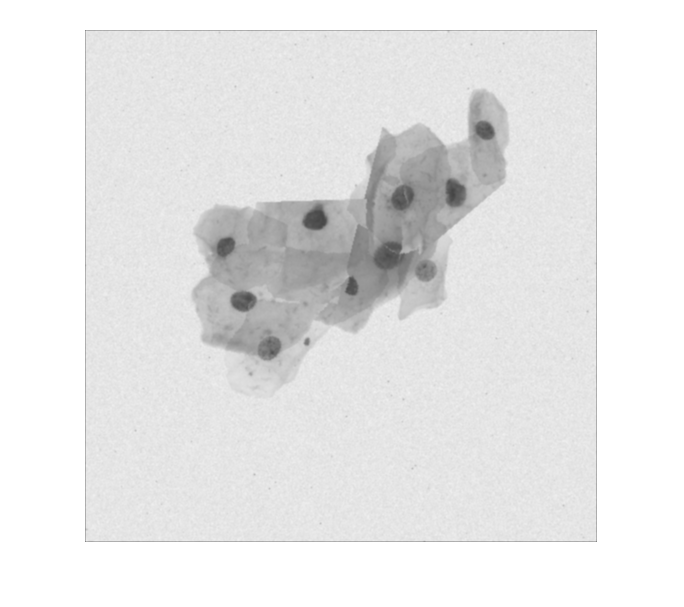

I2 = imread('citocells.bmp');
imshow(I2);

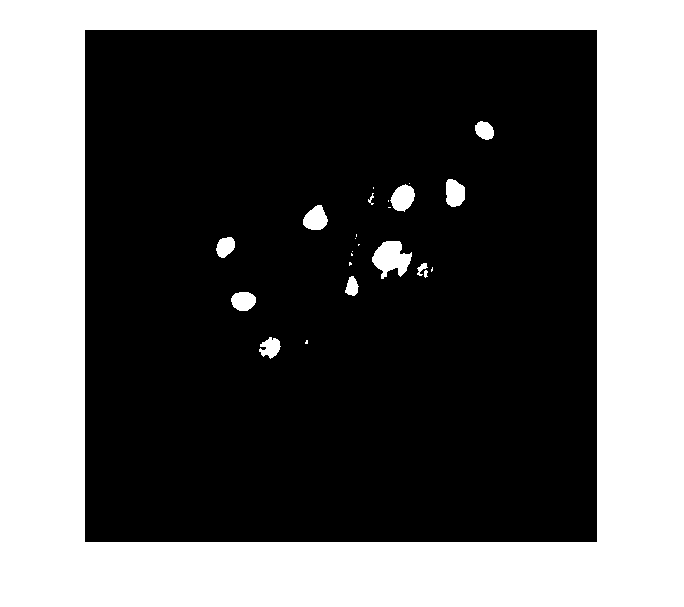

FG = I2 < 129;
imshow(FG);

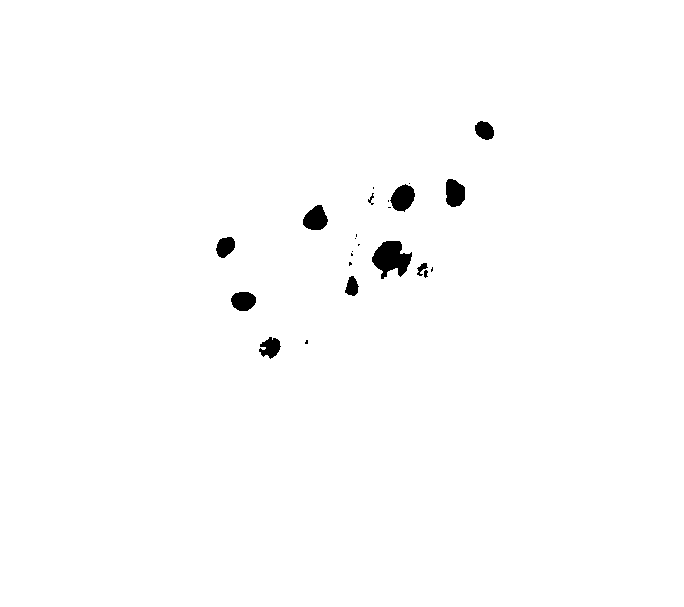

BG = not(FG);
imshow(BG, []);

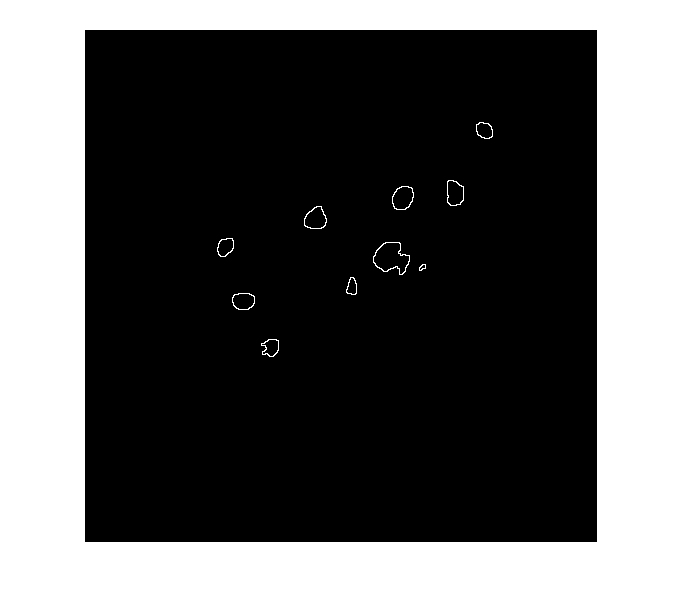

TD = bwdist(BG, 'euclidean');
TD = -TD;
TD(BG) = -Inf;
TDF = medfilt2(TD);
WS = watershed(TDF);
RGB = (WS == 0);
RGB = im2uint8(RGB);
imshow(RGB);

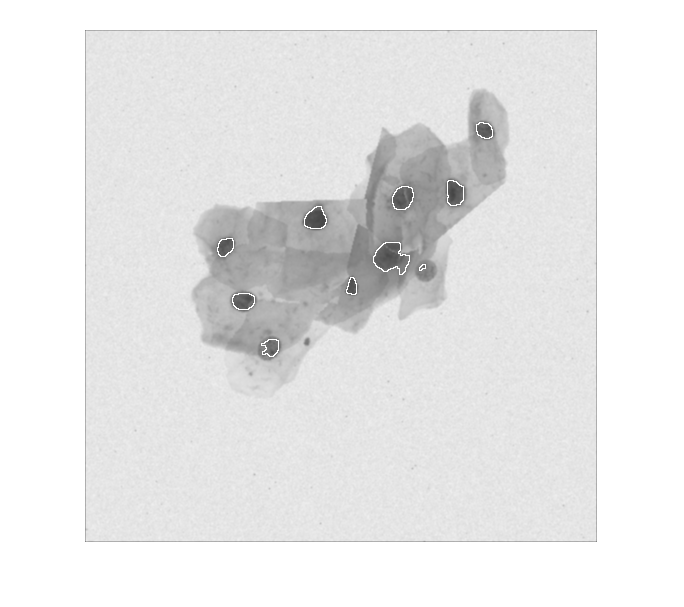

Res = I2 + RGB;
imshow(Res);

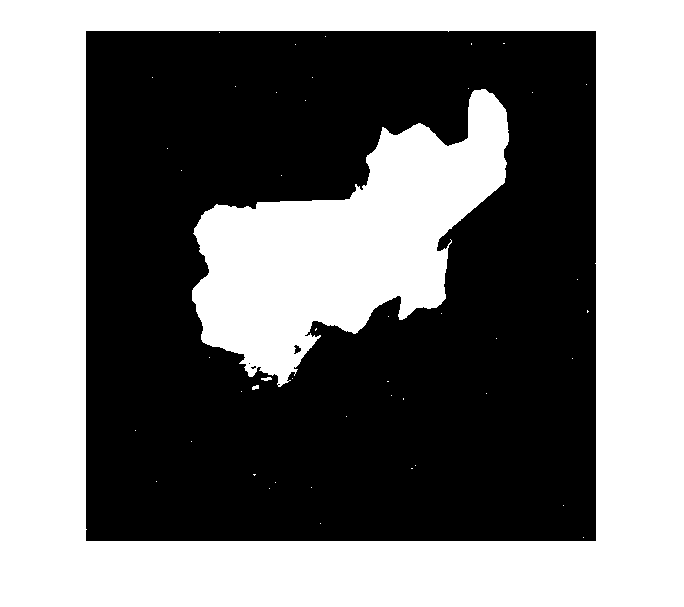

BW2 = I2 < 210;
imshow(BW2);

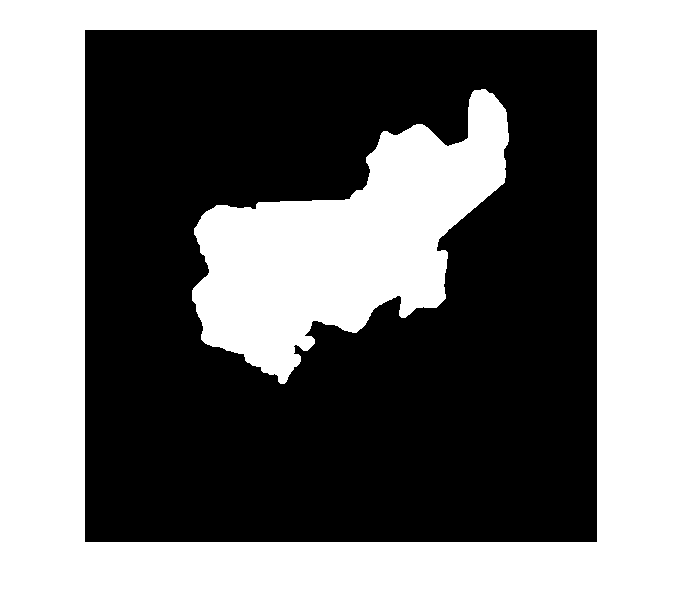

C = imopen(BW2, strel('disk', 5));
imshow(C, []);

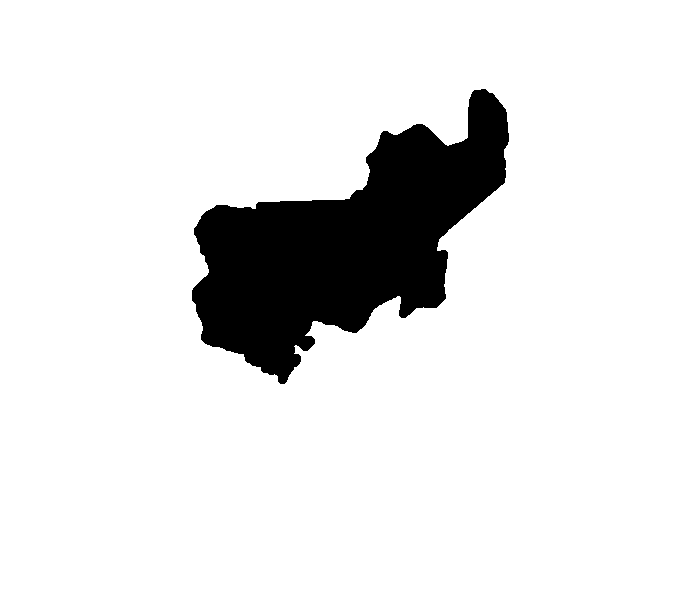

BG2 = not(C);
imshow(BG2);

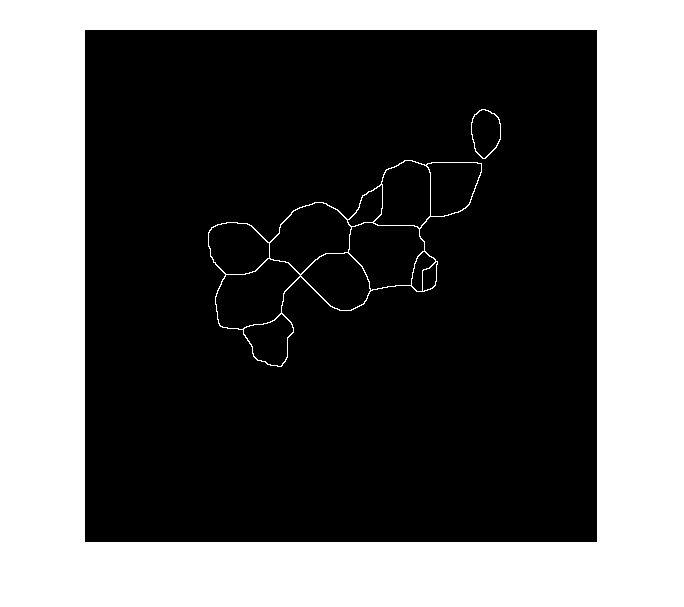

TD2 = bwdist(BG, 'euclidean');
TD2 = -TD2;
TD2(BG2) = -Inf;
TDF2 = medfilt2(medfilt2(medfilt2(TD2)));
WS2 = watershed(TDF2);
RGB2 = (WS2 == 0);
RGB2 = im2uint8(RGB2);
imshow(RGB2);

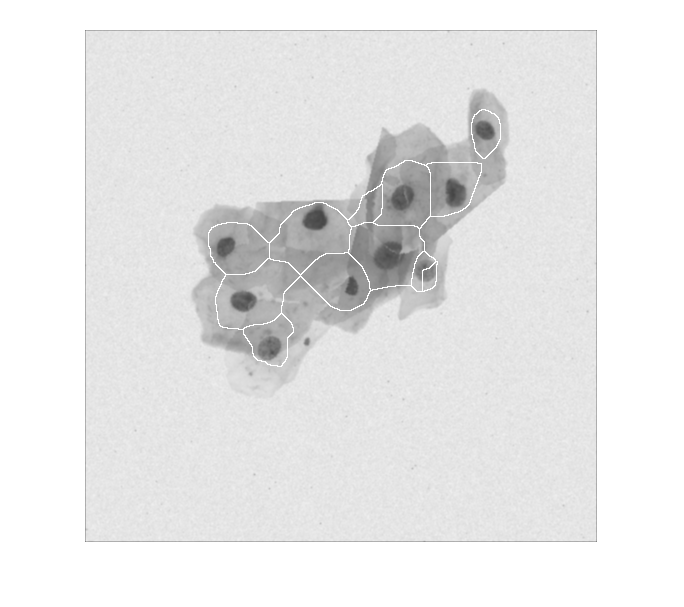

Res2 = I2 + RGB2;
imshow(Res2);

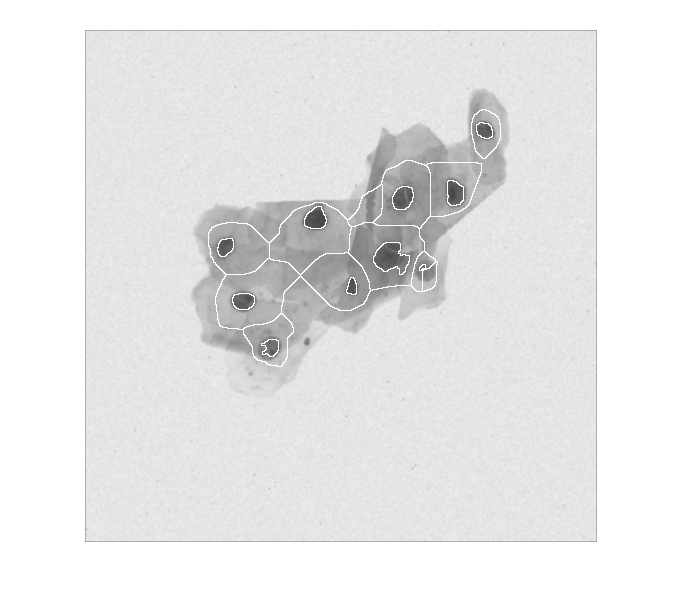

Result = I2 + RGB + RGB2;
imshow(Result);